# Assignment 2-2: Obtaining the ACS domain.

## Loading data

brainCoilsData = load('brain_coil.mat');
brainCoils = brainCoilsData.brain_coil_tmp;

[phaseLength, freqLength, channels] = size(brainCoils);
disp(size(brainCoils));  % Phases, Frequencies, Coils

   120   128     5



## Convert to Fourier Domain with 2D Fast Fourier Transform

Don't forget to use fftshift and ifftshift.

fullKspace = ifftshift(fft2(fftshift(brainCoils)));

Checking if k-space was generated correctly.

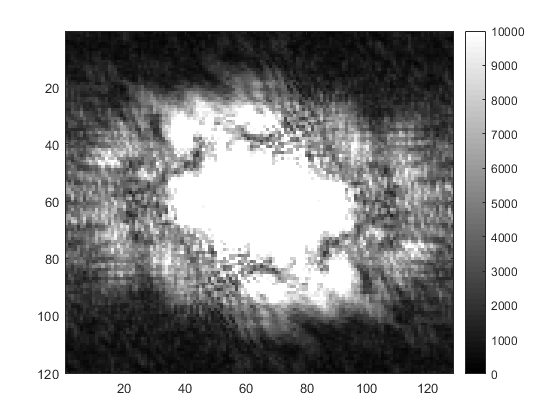

imagesc(rsos(fullKspace), [0, 10000]);
colormap('gray');
colorbar();

## Setting parameters for later use.

downSamplingRate = 3;
acsLength = 6;

## Making the mask

Creating a mask for the downsampling and the acs lines.

mask = zeros(size(fullKspace));  % Making a mask for the brain coils.

acsStart = floor((phaseLength - acsLength) ./ 2);
acsFinish = acsStart + acsLength;

for i=1:phaseLength  % Goes along the phase encoding axis.
    if rem(i, downSamplingRate) == 0
        mask(i, :, :) = 1;  % Broadcasting the value of 1 to mask(i, :, :).
    end
    
    % Separated the 2 if conditions to make the code more legible.
    if (acsStart < i) && (i <= acsFinish)
        mask(i, :, :) = 1;
    end    
end
assert(isequal(size(mask), size(brainCoils)), 'Mask size is incorrect.')

## Displaying mask.

This code functions to check whether the mask has been made correctly.

White lines indicate 1's. Black lines indicate 0's.

All values should be either 0 or 1. Thepresence of any other value indicates an error.

There should be a white band in the middle, with striped lines surrounding it.

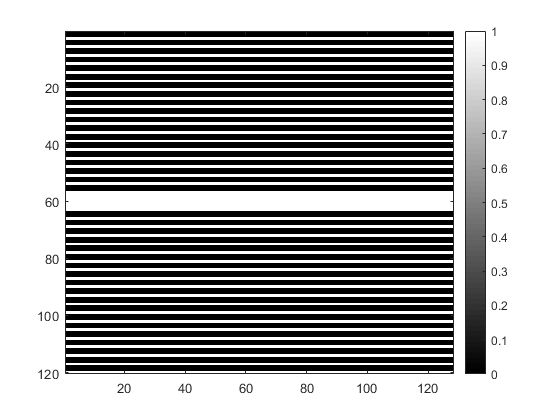

dispMask = mean(mask, 3);
imagesc(dispMask);
colormap('gray');
colorbar();

## Generating the down-sampled k-space image

Obtain the Hadamard product (elementwise matrix multiplication) between the full k-space data and the mask.

Hint: use the .* operator, not the * operator, which does matrix multiplication.

% Elementwise (Hadamard) product (multiplication) of matrices.
downSampledKspace = fullKspace .* mask;
assert(isequal(size(downSampledKspace), size(brainCoils)), 'Reconstruction is of the wrong shape.')

Visualizing downsampled k-space.

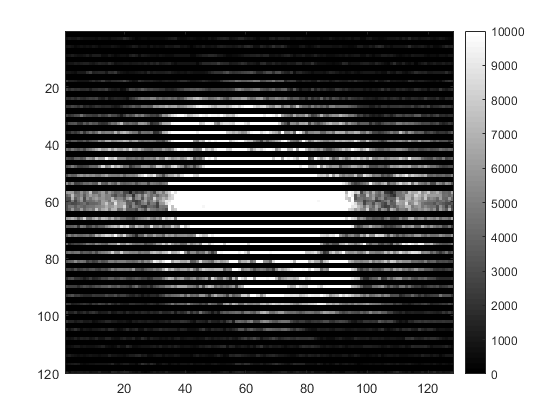

imagesc(rsos(downSampledKspace), [0, 10000]);
colormap('gray');
colorbar();

## Generating downsampled coil data from downsampled k-space.

dsBrainCoils = ifftshift(ifft2(fftshift(downSampledKspace)));

% Using rsos (root sum of squares) to make visualization possible.
recon = rsos(dsBrainCoils);
original = rsos(brainCoils);
assert(isequal(size(recon), size(original)), 'The reconstruction has an incorrect size.')

## Final visualization of data.

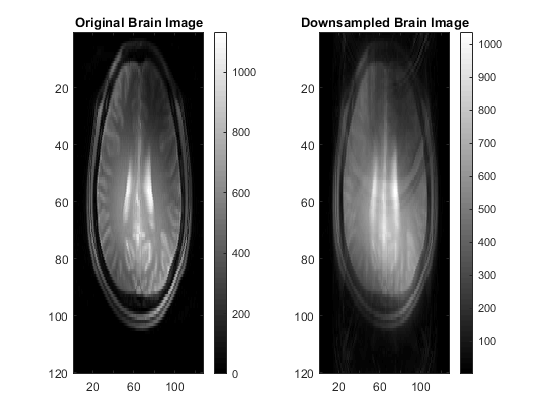

figure;
colormap('gray');

subplot(1, 2, 1);
imagesc(original);
title('Original Brain Image');
colorbar();

subplot(1, 2, 2);
imagesc(recon);
title('Downsampled Brain Image');
colorbar();

## Checking for scaling issues.

% Display minima and maxima of original data.
disp(min(recon, [], 'all'));

   1.4652e-14



disp(max(recon, [], 'all'));

   1.0374e+03



disp(min(brainCoils, [], 'all'));

   -1.2590



disp(max(brainCoils, [], 'all'));

   1.0876e+03



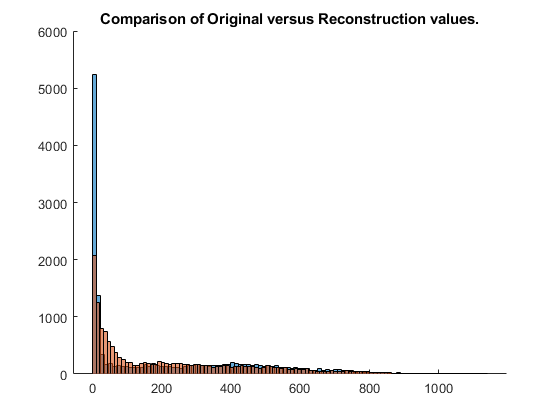


% Plotting Differences between rsos treated original data and recon data.
figure;
colormap('default');

hold on
histogram(original(:), 100, 'FaceColor','auto');
histogram(recon(:), 100, 'FaceColor','auto');
title('Comparison of Original versus Reconstruction values.')
hold off